clc; clear; close all;

% -----------------------------
% Cargar datos como tabla
% -----------------------------
filename = 'Five_times_Kinematics_HT_Query_MATLAB.xlsx';
numericData = readtable(filename);  % Mantiene los nombres de las variables

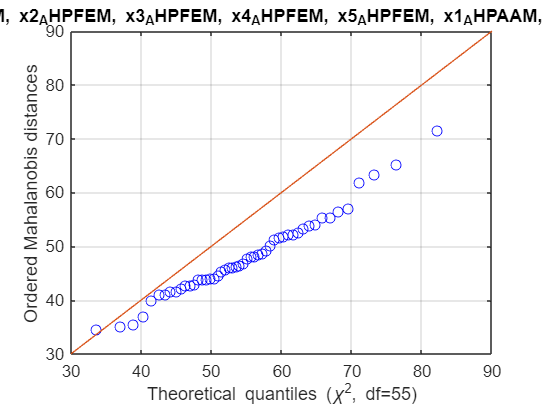

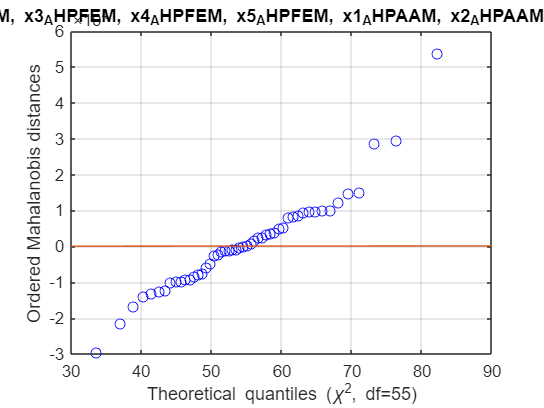

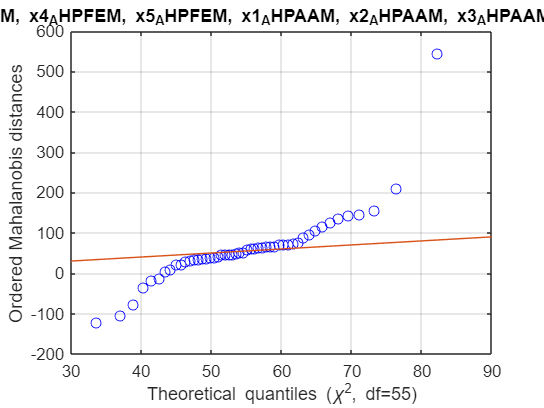

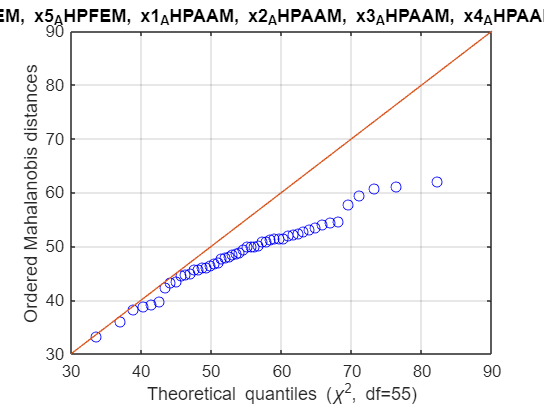

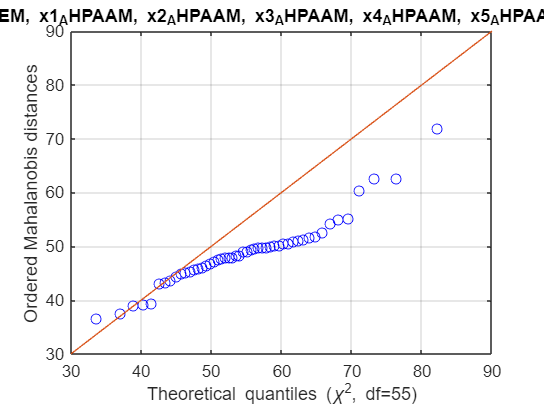

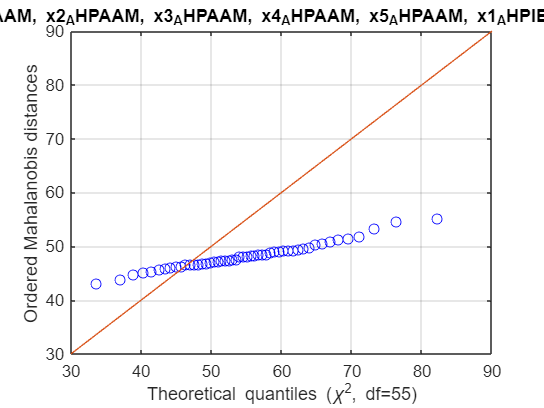

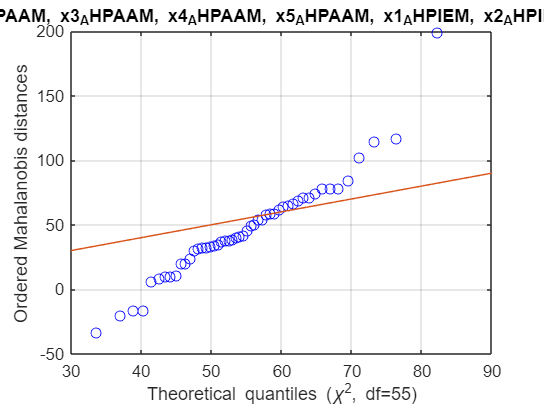

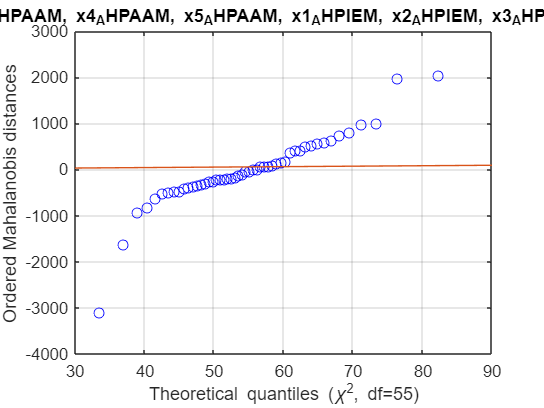

X = numericData{:,:};               % Datos numéricos
[n, p] = size(X);                   % n = muestras, p = variables

% -----------------------------
% Chi-square plots de 55 en 55 dimensiones
% Empezando desde la 3ra columna
% -----------------------------
start_dim = 3;
window_size = 55;

for start_col = start_dim : (p - window_size + 1)
    cols = start_col : (start_col + window_size - 1);
    X_sub = X(:, cols);  % Subconjunto de 5 columnas

    % Media y covarianza
    mean_vec = mean(X_sub);
    cov_mat = cov(X_sub);
    inv_cov = inv(cov_mat);

    % Distancia de Mahalanobis
    mahal_dist = zeros(n, 1);
    for i = 1:n
        diff = X_sub(i, :) - mean_vec;
        mahal_dist(i) = diff * inv_cov * diff';
    end

    % Cuantiles teóricos de chi-cuadrado con 5 grados de libertad
    chi2_q = chi2inv(((1:n)' - 0.5) / n, window_size);

    % Obtener nombres de variables para título
    varNames = numericData.Properties.VariableNames(cols);
    nameStr = strjoin(varNames, ', ');

    % Graficar
    figure;
    plot(chi2_q, sort(mahal_dist), 'bo');
    hold on;
    refline(1, 0);
    xlabel(['Theoretical quantiles (\chi^2, df=' num2str(window_size) ')']);
    ylabel('Ordered Mahalanobis distances');
    title(['Chi-square plot: ' nameStr]);
    grid on;
end